## **BME 3890: Analysis of Brain Networks**

**Final Project- Group 4**

Hank Golding, Joseph Sexton, Vidhya Shunmugasundaram

Project Submitted: 12/05/22

**PROJECT QUESTION: **In what ways do the group differences detected between autistic and non-autistic samples vary based on (1) the number of iterations of *k*-means clustering conducted for parcellation and (2) the threshold used to scrub the parcel-correlation matrix?

**Motivations: **Autism spectrum disorder (ASD) is a neurodevelopmental disorder estimated to affect 1 in 44 children in the United States. Understanding the pathways in the brain that characterize ASD is a common goal of neurologists interested in improving interventions and services for autistic clients. However, as discussed at several points in class, there are a number of important computational decisions from preprocessing to final paper that may affect ultimate conclusions. Here, we adapt a sample from the Autism Brain Imaging Data Exchange (ABIDE) and explore group differences in autistic (n=10) and non-autistic (n=10) brain networks. We parcellate these networks using a k-means clustering method. Following the first iteration of k-means, we take the resulting parcellation and use it as a template in the following k-means. This process is repeated eight times, i.e., resulting in eight different parcellations, mirroring real-world best practice where early schemes are used as baselines for future clustering. Then, group differences between the parcel correlations are compared between the autistic and non-autistic samples. Correlations were assessed and scrubbed at three different thresholds of *t*-statistic: *t* = 1.5, 2, and 2.5. In sum, we therefore observed group differences across eight different iterations of *k*-means at three different thresholds, resulting in 24 different parameterizations of group differences. Our ultimate question was: in what ways do the resulting group differences vary based on the number of iterations of *k*-means clustering and threshold of *t*-statistic?

**Parcellation and Analysis of Data**

clear
tic
all_patients=cell(1,20);

all_patients = 1×20 cell array
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}


all_masks=cell(1,20);

all_masks = 1×20 cell array
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}




%these two could be one for loop- it doesnt change time at all however

%load 10 autistic brains - preprocessed functional imaging data + mask
for jj=1:10
    temp_time=niftiread("D:/project/Autistic/A"+jj+"_func_preproc.nii");
    all_masks{jj}=niftiread("D:/project/Autistic/A"+jj+"_mask.nii");
    %norm 1 and mean 0 for each time point in each voxel
    temp_time=temp_time-mean(temp_time,4);
    temp_time=temp_time./vecnorm(temp_time,2,4);
    all_patients{jj}=temp_time;
end

jj = 1

jj = 2

jj = 3

jj = 4

jj = 5

jj = 6

jj = 7

jj = 8

jj = 9

jj = 10


%load data in same manner for 10 non autistic brains
for kk=11:20
    temp_time=niftiread("D:/project/Not Autistic/NA"+(kk-10)+"_func_preproc.nii");
    all_masks{kk}=niftiread("D:/project/Not Autistic/NA"+(kk-10)+"_mask.nii");
    temp_time=temp_time-mean(temp_time,4);
    temp_time=temp_time./vecnorm(temp_time,2,4);
    all_patients{kk}=temp_time;
end

kk = 11

kk = 12

kk = 13

kk = 14

kk = 15

kk = 16

kk = 17

kk = 18

kk = 19

kk = 20


%begin 20 patient concatenation 
kmean_parcel_data=all_patients{1};
%clear already used data - for this large of a dataset really important to
%minimize temporary files / variables
all_patients{1}=[];
for m=2:20
    %concatenate all 20 patients together
    kmean_parcel_data=cat(4,kmean_parcel_data,all_patients{m});
    %clear data after concatentation
    all_patients{m}=[];
end

m = 2

m = 3

m = 4

m = 5

m = 6

m = 7

m = 8

m = 9

m = 10

m = 11

m = 12

m = 13

m = 14

m = 15

m = 16

m = 17

m = 18

m = 19

m = 20

%inspect data
whos kmean_parcel_data

  Name                    Size                         Bytes  Class     Attributes

  kmean_parcel_data      61x73x61x3520            7649185280  double              



%number of timepoints when concatenated
nn=size(kmean_parcel_data,4);

%preallocate matrix to hold vertex information
combo_timeseries_vertex=zeros(size(kmean_parcel_data,1),size(kmean_parcel_data,2),size(kmean_parcel_data,3),3);

%61, 73, and 61 can be kept as identical imaging protocol means nifti files
%have same number of voxels in each dataset

for jj=1:61
    for ii=1:73
        for mm=1:61
        %sqrt nn/3 gives us equal weight between vertices and timeseries in
        %euclidean distance measurement
        combo_timeseries_vertex(jj,ii,mm,:)=[jj*sqrt(nn/3),ii*sqrt(nn/3),mm*sqrt(nn/3)];
      
        end
    end
end

%concatenate timeseries data and vertex data together

ans =     61    73    61     3


ans =           61          73          61        3520


kmean_parcel_data=cat(4,kmean_parcel_data,combo_timeseries_vertex);

combo_timeseries_vertex =     35    18     1
    35    19     1
    36    19     1
    29    20     1
    30    20     1
    31    20     1
    32    20     1
    33    20     1
    36    20     1
    37    20     1



%make big timeseries data 2d
kmean_parcel_data=reshape(kmean_parcel_data,[],size(kmean_parcel_data,4));

%find all NaN inputs into kmean_parcel_data
idx = isnan(kmean_parcel_data) == 0;
summer=sum(idx,2)

summer =      3
     3
     3
     3
     3
     3
     3
     3
     3
     3


%if entire row minus vertex information NaN, make entire row NaN
kmean_parcel_data(summer<5,:)=NaN;


ans =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN


ans =     0.0934    0.0598   -0.0161   -0.0614   -0.0412    0.0049    0.0161   -0.0126   -0.0263    0.0168    0.0848    0.1008    0.0298   -0.0771   -0.1317   -0.0949   -0.0095    0.0496    0.0455    0.0028   -0.0282   -0.0191    0.0178    0.0470    0.0409    0.0015   -0.0428   -0.0629   -0.0574   -0.0525   -0.0668   -0.0769   -0.0340    0.0754    0.1893    0.2130    0.1142   -0.0308   -0.1036   -0.0584    0.0359    0.0760    0.0345   -0.0217   -0.0201    0.0317    0.0628    0.0283   -0.0398   -0.0806


%find index of all voxels with full NaN inputs - these aren't needed for

ans = 0

%anything
idx_nan=find(sum(isnan(kmean_parcel_data),2)==3523)

idx_temp =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


idxxx =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


%make a binary mask of valid voxels
idx_masker=zeros(1,61*73*61);
idx_masker(idx_nan)=1;

%number of valid voxels
s=size(kmean_parcel_data,1);

%eliminate all NaN voxels before k-means parcellation
idx_masker=idx_masker'

idx_masker =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


kmean_parcel_data(idx_nan,:)=[];

%starting number of parcellations
p=250;
[K1, c]=my_kmeans_euc(kmean_parcel_data,p);

i = 1

fractional change: 0.9947


i = 2

fractional change: 0.3858


i = 3

fractional change: 0.1986


i = 4

fractional change: 0.1468


i = 5

fractional change: 0.1298


i = 6

fractional change: 0.1206


i = 7

fractional change: 0.1072


i = 8

fractional change: 0.0968



toc

Elapsed time is 5218.437752 seconds.



%write template parcellation scheme to excel file - in case code crashes or
%for any other reason
writematrix(K1,"template_parcellation.xlsx")

%write file / matrix that records vertices of valid voxels
combo_timeseries_vertex=reshape(combo_timeseries_vertex,[],size(combo_timeseries_vertex,4));
combo_timeseries_vertex=combo_timeseries_vertex./sqrt(nn/3)
combo_timeseries_vertex(idx_nan,:)=[]
writematrix(combo_timeseries_vertex,"vertex_ultra_mask.xlsx")

%get all unique parcellations (only 64 left out of original 250)
uu=unique(K1)

uu =      1
    11
    13
    16
    27
    34
    37
    41
    45
    65



%mu is number of kmeans iterations each patient does (in theory how far
%from template parcellation each patient specific parcellation is)
for mu=2:9


mu = 9


c=size(unique(K1),1);

%preallocate cell for patient specific parcellations
parcel_by_person=cell(1,20);

for jj=1:20
    
    %select single patient timeseries at a given time (always excluding
    %vertex information, with indexing at jj=20 stopping before vertex
    %timeseries
    timeseries_temp=kmean_parcel_data(:,176*jj-175 :176*jj);
    %load patient specific mask
    mask_temp=all_masks{jj};
    mask_temp=reshape(mask_temp,61*73*61,[]);
  
    %make patient specific mask match exclude non valid voxels 
    mask_temp(idx_nan)=[];
    %use parcellation data only from patient specific valid voxels
    K_temp=K1(find(mask_temp==1));
    timeseries_temp=timeseries_temp(find(mask_temp==1),:);

    %initialize parcellation
    X_parc=zeros(c,size(timeseries_temp,2));

    %get centroid locations of template parcellation (specific to patient)
    centroid_center=zeros(c,size(timeseries_temp,2));
    for kk=1:c
        idx = K_temp == uu(kk)    ;
        % logical indexing
        centroid_center(kk, :) = mean(timeseries_temp(idx, :), 1, 'omitnan');
    end
    
    %iteratively parcellate each patient from template, with 'mu'
    %iterations, using previously found centroid centers as starting points
    k_spec=kmeans(timeseries_temp,c,'MaxIter',mu,'Start',centroid_center);
    
    %parcellate each patient
    for i = 1:c   
        idx = k_spec == i;
        % logical indexing
        X_parc(i, :) = mean(timeseries_temp(idx, :), 1, 'omitnan');
    end

    %i think unneccesary artifact - would eliminate all parcels that got
    %eaten in original making of template
    X_parc(all(isnan(X_parc),2),:) = [];    

    parcel_by_person{jj}=X_parc;
end

parcel_by_person = 1×20 cell array
    {64×176 double}    {64×176 double}    {64×176 double}    {64×176 double}    {64×176 double}    {64×176 double}    {64×176 double}    {64×176 double}    {64×176 double}    {64×176 double}    {64×176 double}    {64×176 double}    {64×176 double}    {64×176 double}    {64×176 double}    {64×176 double}    {64×176 double}    {64×176 double}    {64×176 double}    {64×176 double}


%initialize correlation per person 3-d matrix
corr_by_per=zeros(c,c,20);

%size of a parcellated data set
[n,t]=size(X_parc);

%number of permutations
s=1000;

for jj=1:20
    %delete parcel info after using it to make corr matrix
    temp_parc=parcel_by_person{jj};
    parcel_by_person{jj}=[];

    %correlation of parcellated timepoints
    C=corr(temp_parc');
    P1 = zeros(n, n, s);
    P2 = zeros(n, n, s);
    
    
    for i = 1:s
        X1 = temp_parc;
        
        % shuffle each row separately (this has the effect of shuffling
        % timeseries node by node (node timeseries shuffled only within same
        % node
        for j = 1:n
            X1(j, randperm(t)) = temp_parc(j, 1:t);
        end
        
        %shuffle node order
        X2 = temp_parc(randperm(n), :);
        
        % compute null correlations
        C1 = corr(X1');
        C2 = corr(X2');
      
    
        P1(:, :, i) = abs(C1) >= abs(C);
        P2(:, :, i) = abs(C2) + 1e-10 >= abs(C);
        
    end
    
    %p-value matrix for null hypothesis about node order
    P1 = mean(P1, 3);
    %p-value matrix for null hypotehtis about timeseries order
    P2 = mean(P2, 3);
    P=(P1<.05 & P2<.05);
    corr_by_per(:,:,jj)=C.*P;
end
%write matrix of correlation by person for number of iterations away from
%template
writematrix(corr_by_per,"correlation_matrix_full_with_"+mu+"iterations.xlsx")
end

%plotting
for jj=1:20
    temp_corr=corr_by_per(:,:,jj);
    figure,
    
    imagesc(temp_corr)
    title('All ~0 correlations significant, correlation matrix')
    axis square
    colorbar
end
hold off



%NBS start - ended up using NBS toolbox

ss=1000
p_val_corr=zeros(c,c,3)

%%only need to compare triu 
huh=triu(null,1)

for jj=1:ss
    idx_nbs=randi([1,3],1,2);
    null=mean(corr_by_per(:,:,idx_nbs),3);
    
    p_val_temp= abs(null)>=abs(corr_by_per);

    p_val_corr=p_val_corr+p_val_temp;
    
end
p_val_corr=p_val_corr./ss
p_val_corr=mean(p_val_corr,3)

imagesc(p_val_corr)

**Figure Generation through NBS Toolbox**

We complete permutation testing using the NBS toolkit as well, which conducts a large number of permutations (we conducted 5000 for each test).

% save patient correlation matrices as .mat files for each # of iterations
two_iter = xlsread("correlation_matrix_full_with_2iterations.xlsx");
whos two_iter
two_iter3d = reshape(two_iter, [64 64 20]);
save('two_iter3d.mat', "two_iter3d");

three_iter = xlsread("correlation_matrix_full_with_3iterations.xlsx");
whos three_iter
three_iter3d = reshape(three_iter, [64 64 20]);
save('three_iter3d.mat', "three_iter3d");

four_iter = xlsread("correlation_matrix_full_with_4iterations.xlsx");
whos four_iter
four_iter3d = reshape(four_iter, [64 64 20]);
save('four_iter3d.mat', "four_iter3d");

five_iter = xlsread("correlation_matrix_full_with_5iterations.xlsx");
whos five_iter
five_iter3d = reshape(five_iter, [64 64 20]);
save('five_iter3d.mat', "five_iter3d");

six_iter = xlsread("correlation_matrix_full_with_6iterations.xlsx");
whos six_iter
six_iter3d = reshape(six_iter, [64 64 20]);
save('six_iter3d.mat', "six_iter3d");

seven_iter = xlsread("correlation_matrix_full_with_7iterations.xlsx");
whos seven_iter
seven_iter3d = reshape(seven_iter, [64 64 20]);
save('seven_iter3d.mat', "seven_iter3d");

eight_iter = xlsread("correlation_matrix_full_with_8iterations.xlsx");
whos eight_iter
eight_iter3d = reshape(eight_iter, [64 64 20]);
save('eight_iter3d.mat', "eight_iter3d");

nine_iter = xlsread("correlation_matrix_full_with_9iterations.xlsx");
whos nine_iter
nine_iter3d = reshape(nine_iter, [64 64 20]);
save('nine_iter3d.mat', "nine_iter3d");

% save template parcellation and vertex mask as .mat files
template_parcellation = xlsread("template_parcellation.xlsx");
whos template_parcellation
save('template_parc.mat', "template_parcellation");

vertex_mask = xlsread("vertex_ultra_mask.xlsx");
whos vertex_mask
save('vertex_mask.mat', "vertex_mask");

% create parcellated timeseries matrix from kmeans mapping
% NOTE! 64 parcels but they are still numbered up to 248
parc_xyz = zeros(64, 3);
j = 1;
for i=1:248
    voxels = vertex_mask(template_parcellation==i,:);
    if length(voxels) > 0
        parc_xyz(j,1) = mean(voxels(:, 1), 'omitnan');
        parc_xyz(j,2) = mean(voxels(:, 2), 'omitnan');
        parc_xyz(j,3) = mean(voxels(:, 3), 'omitnan');
        j = j+1 
    end
end

% convert xyz coordinates to mni space for NBS toolbox use
[x y z outtype] = mni2orFROMxyz(parc_xyz(:,1), parc_xyz(:,2), parc_xyz(:,2),3, 'xyz')

new_parc = [x y z];

% save new coordinates for NBI toolbox use
save('parc_coordinates.mat', 'new_parc')

**RESULTS:**

**NBS-derived network visualizations for different iterations from template and t-stat thresholds**

Left to right: t > 1.5, t > 2, t > 2.5

**2 iterations:**

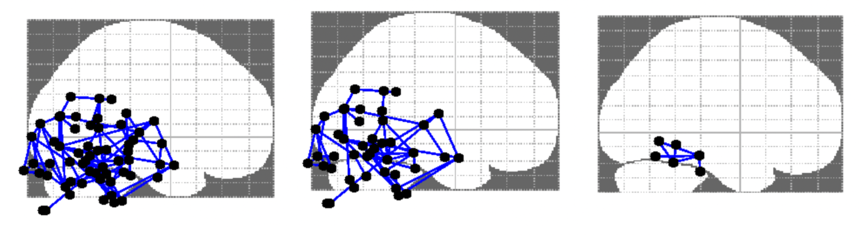

**4 iterations:**

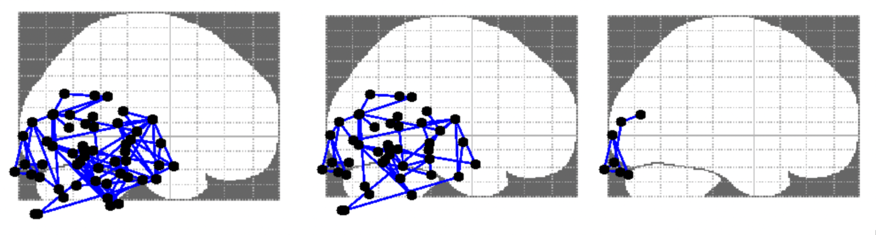

**6 iterations:**

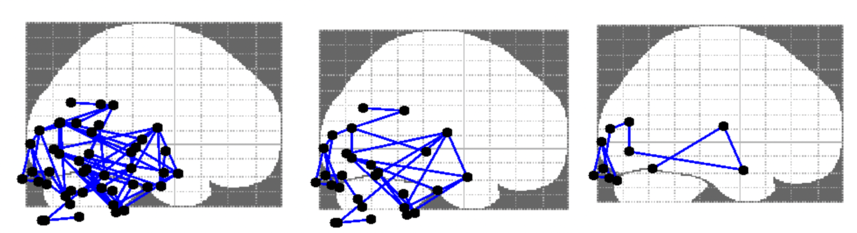

**8 iterations:**

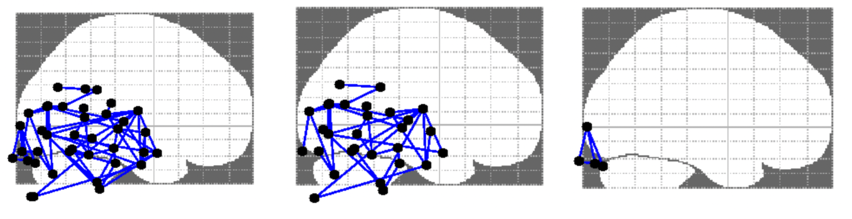

**Interpretation: **With regards to the number of iterations of *k*-means: the more iterations, the fewer significant edge differences between parcels. This is reasonable because, in general, the more iterations take place, the more parsimonious and robust the algorithm tends to become. Consequently, the autistic and non-autistic group differences tend to vanish as they converge on common edge weights. Second, in terms of threshold, the higher the threshold, the fewer group differences are detected. This is unsurprising because more extreme t-values are fewer in number. The importance of thresholding is also unsurprising as it is a common criticism of the use of NBS, as new significant networks can completely emerge or disappear with a change in threshold, or they can contract and expand. 

**Functions**

function [K1, c] = my_kmeans_euc(X, k)
% data dimensions;
[n, t] = size(X);

% 2. make initial random partition
K = randi(k, n, 1);

% 3. iterate 10 times
for i = 1:10
    
    % old partition
    Kold = K;
    
    % 4. compute centroid for each cluster
    X_centroid = zeros(k, t);
    for u = 1:k
       
        X_centroid(u, :) = mean(X(K == (u), :), 1,'omitnan');
    end

    % 5. compute euclidean distance of each node to each centroid (NaN
    % inputs are ignored and not used in computation of distance, however
    % non NaN inputs in same row / concatenated timeseries used)
    
    C = dist_nan_euc(X_centroid,X);
   
    
    % 6. assign each node to it's closest centroid
    [~, K] = min(C, [], 2);


    
    % print number of changes
    disp("fractional change: "+round(mean(Kold~=K), 4))
    if round(mean(Kold~=K), 4)==0
        break
    end
end
K1=K;
c=size(unique(K),1);
end


%this function allows for distances between concatenated timepoints +
%vertex with NaN inputs and centroids to be calculated while omitting NaN
%inputs. MATLAB doesnt allow for 'omitnan' in evaluating pdist2, but does
%allow for it in RMS function

function cc = dist_nan_euc(x,y)
cc=zeros(size(y,1),size(x,1));

for jj=1:size(y,1)
    z=abs(y(jj,:)-x);

    idx = isnan(z) == 0;
    cc(jj,:)=rms(z','omitnan').*sqrt(sum(idx,2)');
end
end
